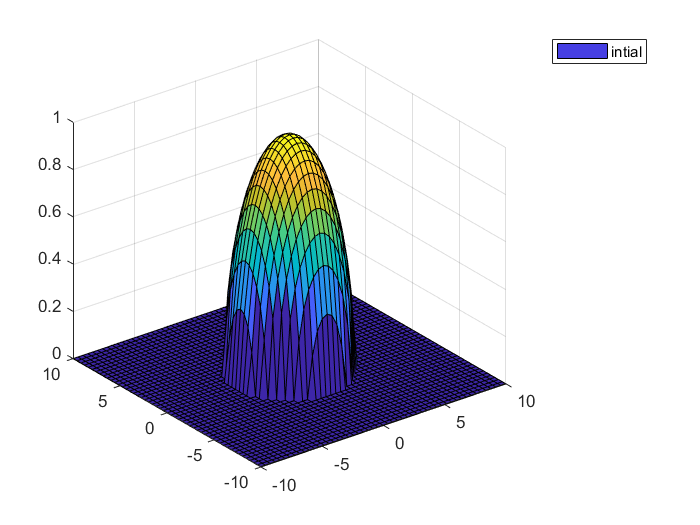

%% ADI 2d, compare with 2d axisymm

clc;clear;
% Parameters
lm = -10; lp = 10;   % Length of the domain 
t0 = 0;      % Initial time
T =5;                % Final time      
Mx = 51;       My = 51;      N = 101;     % Number of grid points
dx = (lp-lm)/(Mx-1);  dy = (lp-lm)/(My-1);  dt = T/(N-1);   % Spatial step size dx  % Spatial step size dy  % Time step size  dt
m = 2;        % power

% Initialize grid
x = [lm :dx :lp] ;  % x row
y = [lm :dy :lp]' ;  % y column
t = [t0: dt: T];
r = (x.^2 + y.^2).^(1/2);

% initial condition
u_simi = @(r,t) max( 1 - m /(4*(m+1)^2) .*(r.*(t+1).^(-1/(2*m+2))).^2  , 0 ).^(1/m).*(t+1).^(-1/(m+1));
u0 = u_simi(r,0)';

u = zeros(Mx,My);
Umax = zeros(N,1);

surf(x,y,u0')
legend ('intial')

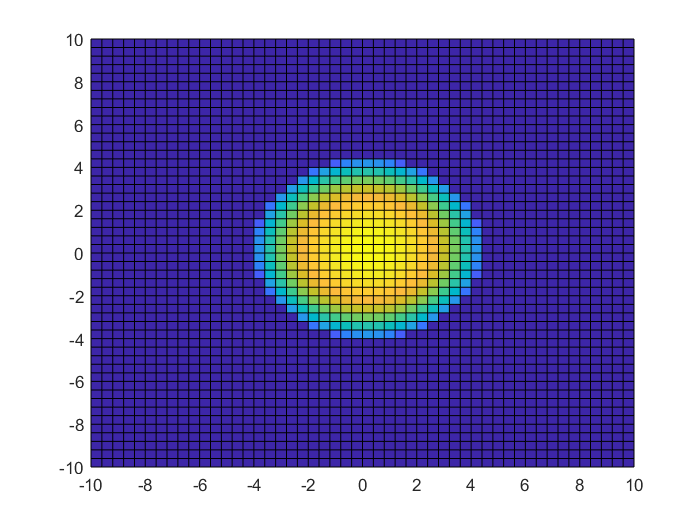

surf(x,y,u0')
view(2)

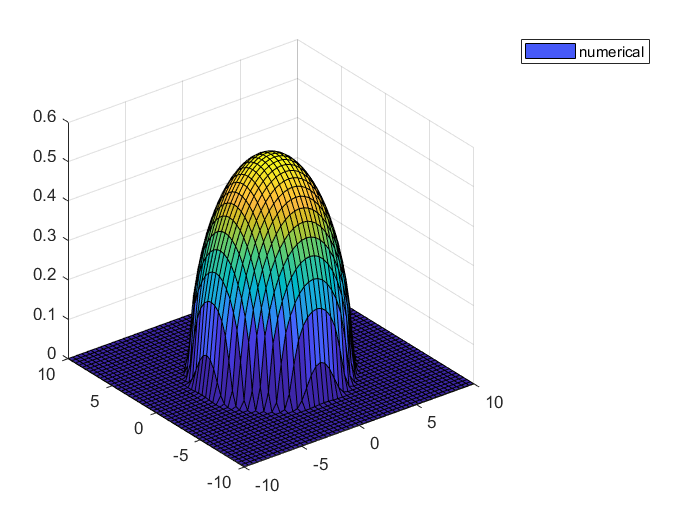


t1 = 0; 
% Time evolution
tk = 0;
while t1<T  
%for jj = 1:N
   u = u0;
   for k=1:5  %(newton iterations at each time)     
       for j = 1:My
           for i = 1:Mx
               uc=u(i,j); % center pt
               if (i==1),  um = u(i+1,j); else, um = u(i-1,j); end 
               if (i==Mx), up = u(i-1,j); else, up = u(i+1,j); end
               if (j==1),  ud = u(i,j+1); else, ud = u(i,j-1); end   
               if (j==My), uu = u(i,j-1); else, uu = u(i,j+1); end
               F(i,j) = uc - u0(i,j) - (dt/dx^2)* ( up^(m+1) - 2*uc^(m+1) ...
                    + um^(m+1) ) - (dt/dy^2) * ( uu^(m+1) - 2*uc^(m+1) + ud^(m+1) );
           end % end i
       end   %F
  
% Two steps
        for j = 1: My
            Jx=zeros(Mx,Mx);
            for  i = 2:Mx-1                
                Jx(i, i-1) = -(m+1)*(dt/dx^2)*u(i-1,j)^m;
                Jx(i, i) = 1+2*(m+1)*(dt/dx^2)*u(i,j)^m;
                Jx(i, i+1) = -(m+1)*(dt/dx^2)*u(i+1,j)^m;
            end
            Jx(1, 1) = 1 +2*(dt/dx^2)*(m+1)*u(1,j)^m;
            Jx(1, 2) = -2*(dt/dx^2)*(m+1)*u(2,j)^m;
            Jx(Mx, Mx-1) = -2*(dt/dx^2)*(m+1)*u(Mx-1,j)^m;
            Jx(Mx, Mx) = 1 +2*(dt/dx^2)*(m+1)*u(Mx,j)^m;
            
            Vx(:,j)= -sparse(Jx) \ F(:,j);            
        end

        for i = 1: Mx
            Jy=zeros(My,My);
            for j = 2:My-1
                Jy(j, j-1) =-(m+1)*(dt/dy^2)*u(i,j-1)^m;
                Jy(j, j) = 1+2*(m+1)*(dt/dy^2)*u(i,j)^m;
                Jy(j, j+1) = -(m+1)*(dt/dy^2)*u(i,j+1)^m;
            end
            Jy(1, 1) = 1 +2*(dt/dy^2)*(m+1)*u(i,1)^m;
            Jy(1, 2) = -(dt/dy^2)*(m+1)*2*u(i,2)^m;
            Jy(My, My-1) = -2*(dt/dy^2)*(m+1)*u(i,My-1)^m   ;
            Jy(My, My) = 1 +2*(dt/dy^2)*(m+1)*u(i,My)^m  ;
            
            Wy(i,:) = sparse(Jy) \ Vx(i,:)';
        end      
        delta_u = Wy;
        u = u + delta_u; 
    
    end    % end netwon iteration k    
    % break
    u0 = u;  %u_old = u_new
    tk = tk+1;
    umax = max(max(u0));
    Umax(tk) = umax;

    t1 = t1 +dt;
end    % end while 

figure(1) 
surf(x,y,u');
legend ('numerical')

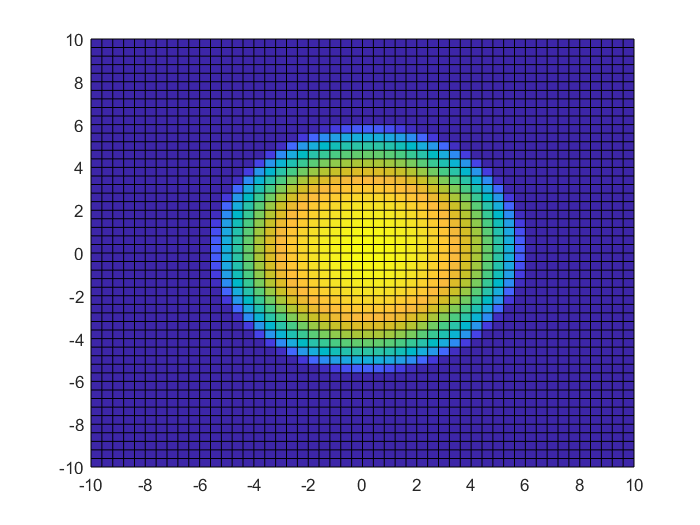

surf(x,y,u')
view(2)

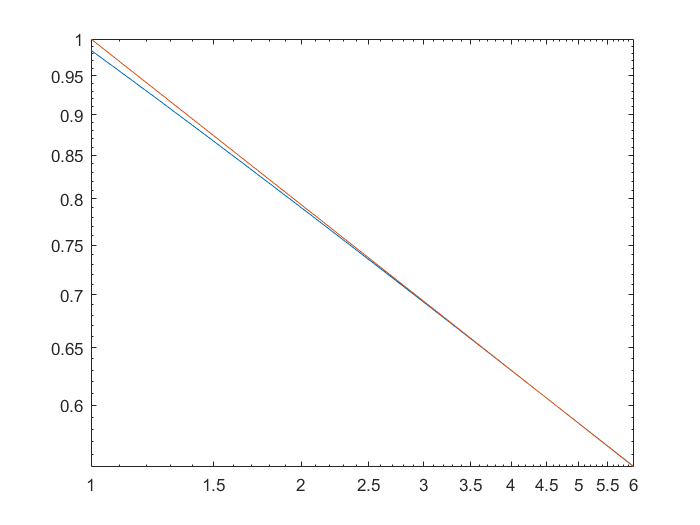


% Umax = max(u)
loglog(t+1,Umax)
hold on
loglog(t+1,(t+1).^(-1/(m+1)));
hold off


% find center
ss = trapz(x,u,2);
Mass = trapz(y,ss);
sux = trapz(x,x.*u,2);
Massux = trapz(y,sux);
suy = trapz(x,y.*u,2);
Massuy = trapz(y,sux);
%x_center = Massux ./ Mass
x_center = round(Massux ./ Mass)

x_center = 0

y_center = round(Massuy ./ Mass)

y_center = 0

%y_center = floor(Massuy ./ Mass)

u;
xx = [x_center :dx :lp];
yy = [y_center :dy :lp]';
rr = (xx.^2 + yy.^2).^(1/2);

for j=1:My
    for i=1:Mx
        if r(i,j) == x_center
            xc = i;
        end
        if r(i,j) == y_center
            yc = j;
        end
    end
end
rr = rr(1,:)

rr =          0    0.4000    0.8000    1.2000    1.6000    2.0000    2.4000    2.8000    3.2000    3.6000    4.0000    4.4000    4.8000    5.2000    5.6000    6.0000    6.4000    6.8000    7.2000    7.6000    8.0000    8.4000    8.8000    9.2000    9.6000   10.0000



%% four directions
ur = u(xc, yc:end)  % ur from the result of ADI

ur =     0.5506    0.5492    0.5451    0.5383    0.5285    0.5157    0.4996    0.4799    0.4562    0.4276    0.3934    0.3517    0.2996    0.2300    0.0994    0.0026    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


% ur = u(xc, yc:-1:1)
% ur = u(xc:end,yc)
% ur = u(xc:-1:1,yc)
% ur_axi from the result of 2d axisymm  (see another file)
ur_axi = [0.552176430273967	0.550820598260424	0.546734737153692	0.539856721675115	0.530078291641151	0.517235649356539	0.501094218908311	0.481323590795566	0.457455401320077	0.428808989190064	0.394349867112538	0.352388021137302	0.299807966321587	0.229338452358484	0.105693704694424	2.06237549913638e-06	2.81570971322212e-51	0	0	0	0	0	0	0	0	0]

ur_axi =     0.5522    0.5508    0.5467    0.5399    0.5301    0.5172    0.5011    0.4813    0.4575    0.4288    0.3943    0.3524    0.2998    0.2293    0.1057    0.0000    0.0000         0         0         0         0         0         0         0         0         0


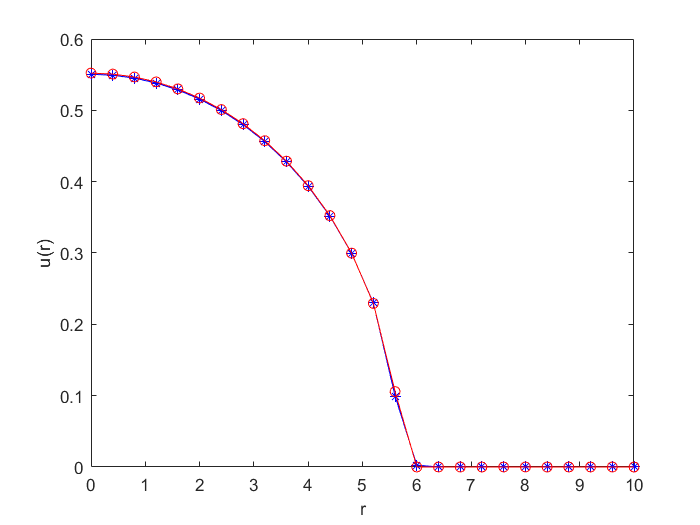

plot(rr,ur,'b*-')
hold on
plot(rr,ur_axi,'rO-')
xlabel('r')
ylabel('u(r)')

legend('')

